# DISPOSITIVO 2

- Ricezione del messaggio inviato da dispositivo 1

- Classificazione della comunicazione e cambio di code rate e modulation order

- Invio dei nuovi parametri di trasmissione

- Se viene ricevuto un keep alive, invia gli ultimi  inviati.

[OFDMParams,dataParams, GeneralParam] = helperSetParameters();
endureCommunication = 1;

### RICEZIONE

Attesa di ricezione


## Establishing connection to hardware. This process can take several seconds.



BER = 0 

Sync symbol found.
Estimating carrier frequency offset ...
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 

Receiver camped.

BER = 5.000000e-01 
Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 2.950299e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC passed
Data decoding completed
------------------------------------------
SNR estimated: 2.380256e+01
Received data in frame 10: Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! 

Passo in trasmissione


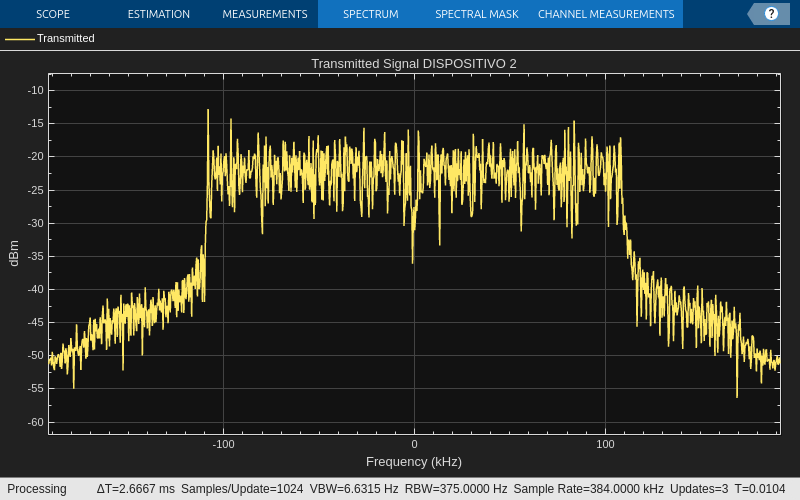

## Establishing connection to hardware. This process can take several seconds.


Attesa di ricezione


## Establishing connection to hardware. This process can take several seconds.



BER = 0 

Sync symbol found.
Estimating carrier frequency offset ...
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 

Receiver camped.

BER = 5.000000e-01 
Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 2.958154e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 16QAM, codeRate=2/3, and FFT Length=128


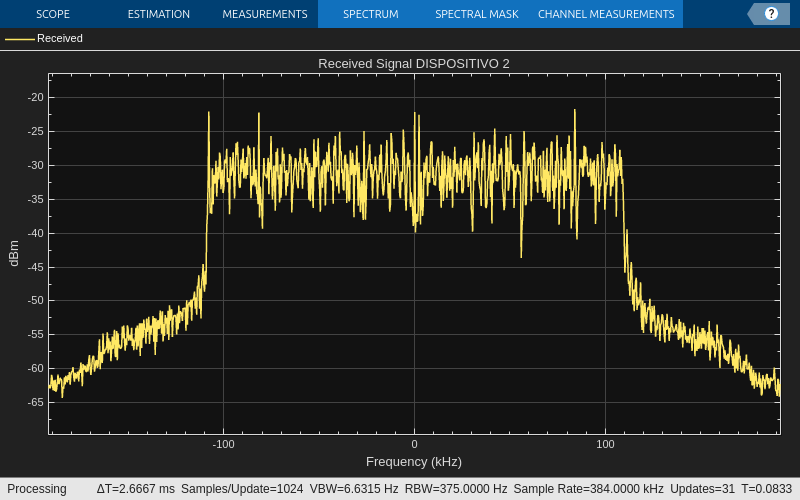

Error using vitdec (line 312)
The input code length must be an integer multiple of the number of ones in the
puncture pattern parameter.

Error in helperOFDMRx>OFDMDataRecovery (line 453)
vitOut = vitdec((vitDecIn(1:end-sysParam.trBlkPadSize)), ...

Error in 

while endureCommunication
    fprintf('Attesa di ricezione\n');
    [rxFlag, params] = helperReceiverModule(GeneralParam, OFDMParams, dataParams);
    if ~rxFlag
        endureCommunication = 0;
    else
        fprintf('Passo in trasmissione\n');
        GeneralParam.message = params;
        GeneralParam.carrier_frequency = GeneralParam.carrier_frequency - 0.001;
        helperTrasmissionModule(GeneralParam,OFDMParams, dataParams);
    end
    pause(3);
    GeneralParam.carrier_frequency = GeneralParam.carrier_frequency + 0.001;
end

fprintf('Comunicazione terminata\nNon è stato ricevuto nulla!\n');